# 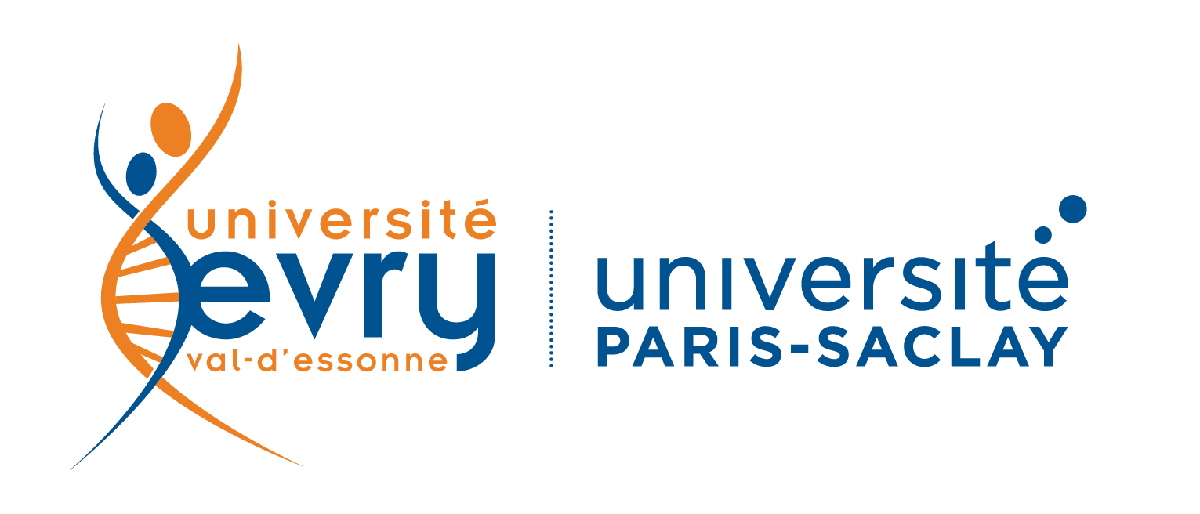

# **M2 E3A SAAS- Flight Modeling and Control**

## **Université d'Évry Paris-Saclay**

**Made by:** Minota Matewos DACHE,  **ID:** 20235671

**Email: **minotadache@gmail.com

## 1.   Introduction

The control of an aircraft pitch is governed by the longitudinal dynamics, using a linear model obtained under some assumptions. The autopilot that will be designed will control the pitch of an aircraft. 

## 2.   Objectives of the Lab

- Familiarization with modeling and simulation with MATLAB/Simulink

- Linear control systems: linearization and stabilization

- Design an autopilot for a drone using the "Exact Linearization" approach and other nonlinear approaches.

- Stabilization and trajectory tracking control.

# **3.   Part I**

**Task 1****: Analyze the provided Simulink model**

The provided drone model is a 6-degree-of-freedom (6DoF) model featuring 12 states, where each pair of states represents a two-block derivative of a single degree of freedom.

The state space vector, denoted as X, captures the essential states of the Unmanned Aerial Vehicle (UAV). It is expressed as:


$$X = [ x_1,  x_2 ,   x_3 , x_4 , x_5 , x_6 , x_7 , x_8 , x_9 , x_{10} , x_{11} , x_{12}]^T
$$


This state vector can be further articulated in terms of linear and angular accelerations, resulting in:


$$\(X = [x, u, y, v, z, w, \dot{\phi}, \dot{p}, \dot{\theta}, \dot{q}, \dot{\psi}, \dot{r}]^T\)
$$


The control input of the quadcopter model, represented by U, consists of four components:


$$\(U = [u_1, u_2, u_3, u_4]^T\)
$$


Here, $u_1 =
$ total thrust input,  $u_2$= roll control input, $u_3
$= pitch control input, and $u_4
$= yaw control input.

After decoupling the longitudinal and lateral motions, the control inputs are redefined as follows:


$$\(U = [u_1, u_2, u_3, u_4, u_5]^T\)
$$


Also the model exhibits strong non-linearity due to the interdependence among states, involving functions such as "sin" and "cos." The nonlinear UAV model can be expressed as a set of differential equations that govern the dynamics of the system. 

The mathematical representation of these equations is provided below:

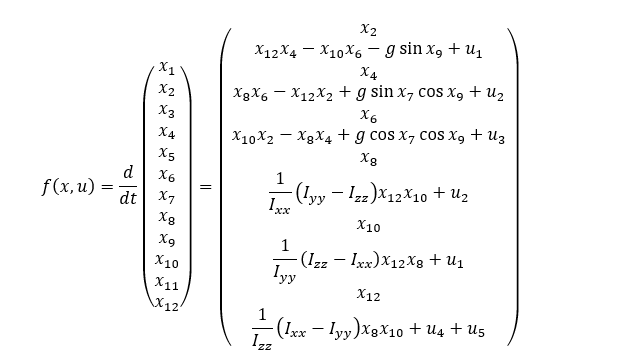

**Task 2: Compute the equilibrium points of the system and show that the origin is an equilibrium point.**

To determine the system's equilibrium point, it is only necessary to equate all nonlinear state equations to zero, as illustrated by:


$$\dot X =[\dot X_1 ,\dot X_2 , \dot X_3, \dot X_4 , \dot X_5, \dot X_6,\dot X_7 , \dot X_8 , \dot X_9 , \dot X_{10} , \dot X_{11} , \dot X_{12}]^T = 0$$


that is explicity 


$$   \dot X_1 = X_2=0 \\
   \dot X_2 = (X_{12} X_4 - X_{10} X_6) - g\sin X_9 + u_1 =0 \\
    \dot X_3 = X_4 =0\\
    \dot X_4 = (X_8 X_6 - X_{12} X_2 + 9\sin X_7 \cos X_9) - u_2 =0\\
   \dot X_5= X_6 =0\\
   \dot X_6 = (X_{10} X_2 - X_8 X_4 + 9\cos X_7 \cos X_9) + u_3 =0\\
    \dot X_7 = X_8=0 \\
   \dot X_8 = \frac{1}{I_{xx}}(I_{yy} - I_{zz}) X_{12} X_{10} + u_2 =0 \\
    \dot X_9 = X_{10}=0 \\
   \dot X_{10} = \frac{1}{I_{yy}}(I_{zz} - I_{xx}) X_{12} X_8 + u_1 =0\\
   \dot X_{11} = X_{12} =0\\
   \dot X_{12} = \frac{1}{I_{zz}}(I_{xx} - I_{yy}) X_8 X_{10} + u_4 + u_5 =0$$


By replacing $X_2 =X_4 = X_6 = X_8 = X_{10} = X_{12} = 0 , $ and setting all control inputs $u_1 =u_2 = u_3 = u_4 = u_5  = 0 , $ then we will be left with the following equations:- 


$$-g*\sin X_9 =0\\ g*\sin X_7 \cos X_9 = 0 \\ g* \cos X_7 \cos X_9 = 0$$


Thus, from these three equations, it can be inferred that X9=0 and X7 = 0. Consequently, in this scenario, the origin can be regarded as an equilibrium point, given that X1, X3, and X5 can be set to zero as they are absent from the nonlinear equations.

# **Part 2 : Simulink Modeling and Simulation**

## 1. Linear longitudinal and lateral control

**Q1.** Compute the linearized models around the origin of each model ?

Given the decoupled lateral and longitudinal motions of the drone:

**Longitudinal motion :                           Lateral motion :**


$$\dot x_1 = x_2 \\
\dot x_2 = -g \sin(x_9) + u_1 \\
\dot x_9 = x_{10} \\
\dot x_{10} = b_2 u_1$$
                                
$$\dot x_3 = x_4 \\
\dot x_4 = g \sin(x_7) + u_2 \\
\dot x_7 = x_8 \\
\dot x_8 = b_1u_2$$


Since the non linearties are introduced by the sin of angle we get rid of it so make $\sin X_9 = X_9$ and $\sin X_7 = X_7$. i.e we linearize around the origion. So we get the following equations of motions


$$\dot x_1 = x_2 \\
\dot x_2 = -g * x_9 + u_1 \\
\dot x_9 = x_{10} \\
\dot x_{10} = b_2 u_1$$
                                   
$$\dot x_3 = x_4 \\
\dot x_4 = g * x_7 + u_2 \\
\dot x_7 = x_8 \\
\dot x_8 = b_1u_2$$


**Q2.** For each motion, compute a linear controller by state feedback control and pole placement technique.

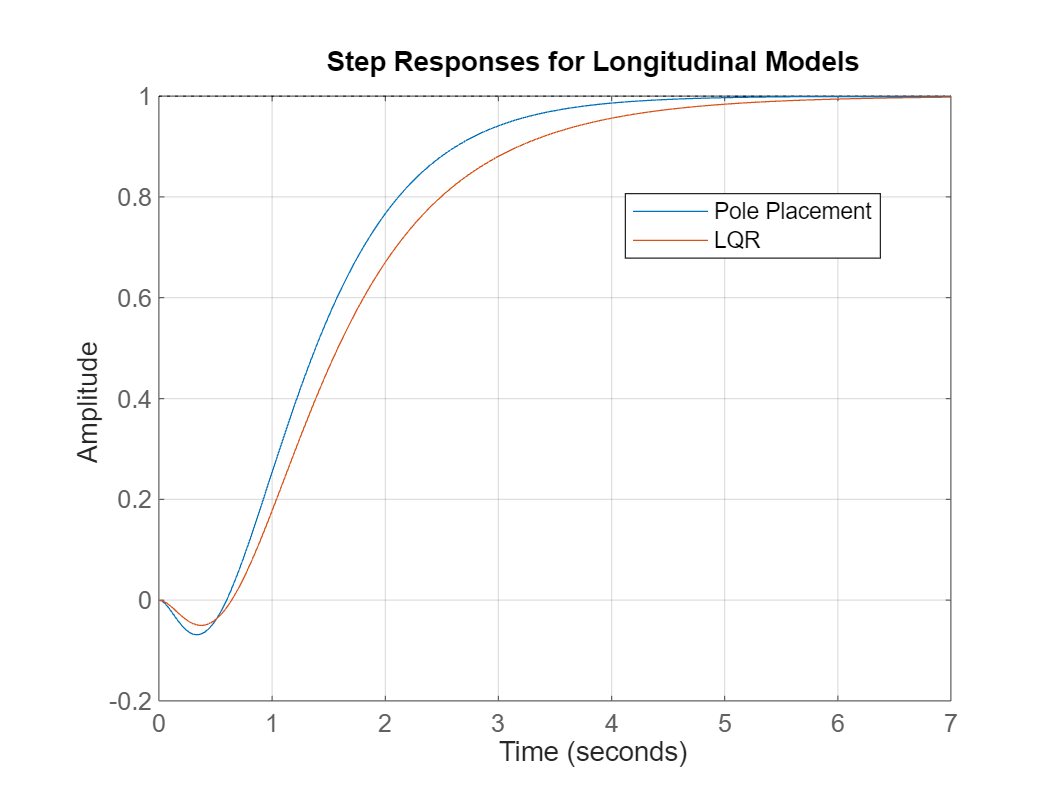

% Drone Linear State Representation for Longitudinal and Lateral Control

% Define gravitational acceleration
g = 9.81; % m/s^2

% Longitudinal System Matrices
A_Long = [0 1 0 0;
       0 0 -g 0;
       0 0 0 1;
       0 0 0 0];
B_Long = [0; 1; 0; 1];

% Lateral System Matrices
A_lat = [0 1 0 0;
       0 0 g 0;
       0 0 0 1;
       0 0 0 0];
B_lat = B_Long; % Using the same input matrix

% Output Matrix Definition
C = [1 0 0 0];
D = 0;

% Pole Placement Control
K_Long = place(A_Long, B_Long, [-2.2 -4.8 -3.7 -1.5]);
K_lat = place(A_lat, B_lat, [-2.2 -4.8 -3.7 -1.5]);

% Create State-Space Models for Longitudinal and Lateral Systems
Long_sys = ss(A_Long - B_Long*K_Long, B_Long, C, D);
Lat_sys = ss(A_lat - B_lat*K_lat, B_lat, C, D);

% Stability and Performance Analysis
% LQR Control Design
Q = 10*eye(4);
R = 1;
L_long = lqr(A_Long, B_Long, Q, R);
L_lat = lqr(A_lat, B_lat, Q, R);

% Create LQR-Based State-Space Models
Long_lqr = ss(A_Long - B_Long*L_long, B_Long, C, D);
Lat_lqr = ss(A_lat - B_lat*L_lat, B_lat, C, D);

% Plot Step Responses for Longitudinal Models
figure;
step(Long_sys/dcgain(Long_sys));
hold on;
step(Long_lqr/dcgain(Long_lqr));
legend('Pole Placement', 'LQR',Location='best');
title('Step Responses for Longitudinal Models');
grid on;
hold off;

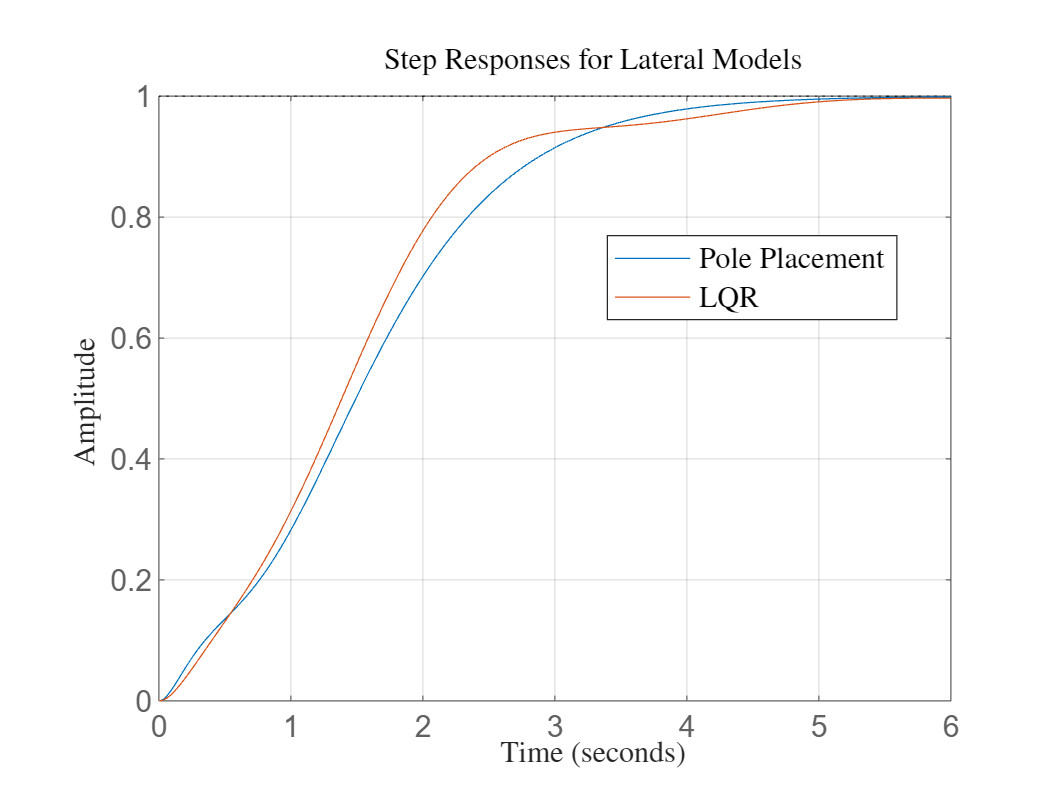

%% Plot Step Responses for Lateral Models
figure;
step(Lat_sys/dcgain(Lat_sys));
hold on;
step(Lat_lqr/dcgain(Lat_lqr));
legend('Pole Placement', 'LQR',Location='best');
title('Step Responses for Lateral Models');
grid on;
hold off;
% Adjust plot aesthetics
set(findall(gcf, '-property', 'FontSize'), 'FontSize', 12);
set(findall(gcf, '-property', 'Interpreter'), 'Interpreter', 'latex');

The system responses exhibit stability under both controllers; however, the LQR controller demonstrates slightly diminished performance compared to the selected pole placement approach. This discrepancy can be attributed to the optimization process inherent in LQR, which may prioritize certain criteria over achieving an exact match with the chosen pole locations.

**Q3.** **Apply the proposed control techniques directly on the nonlinear model. Discuss the results.**

Here we will implement the LQR control method that we have developed for our model on the nonlinear representation of that system. Below is the model of the drone using SIMULINK:

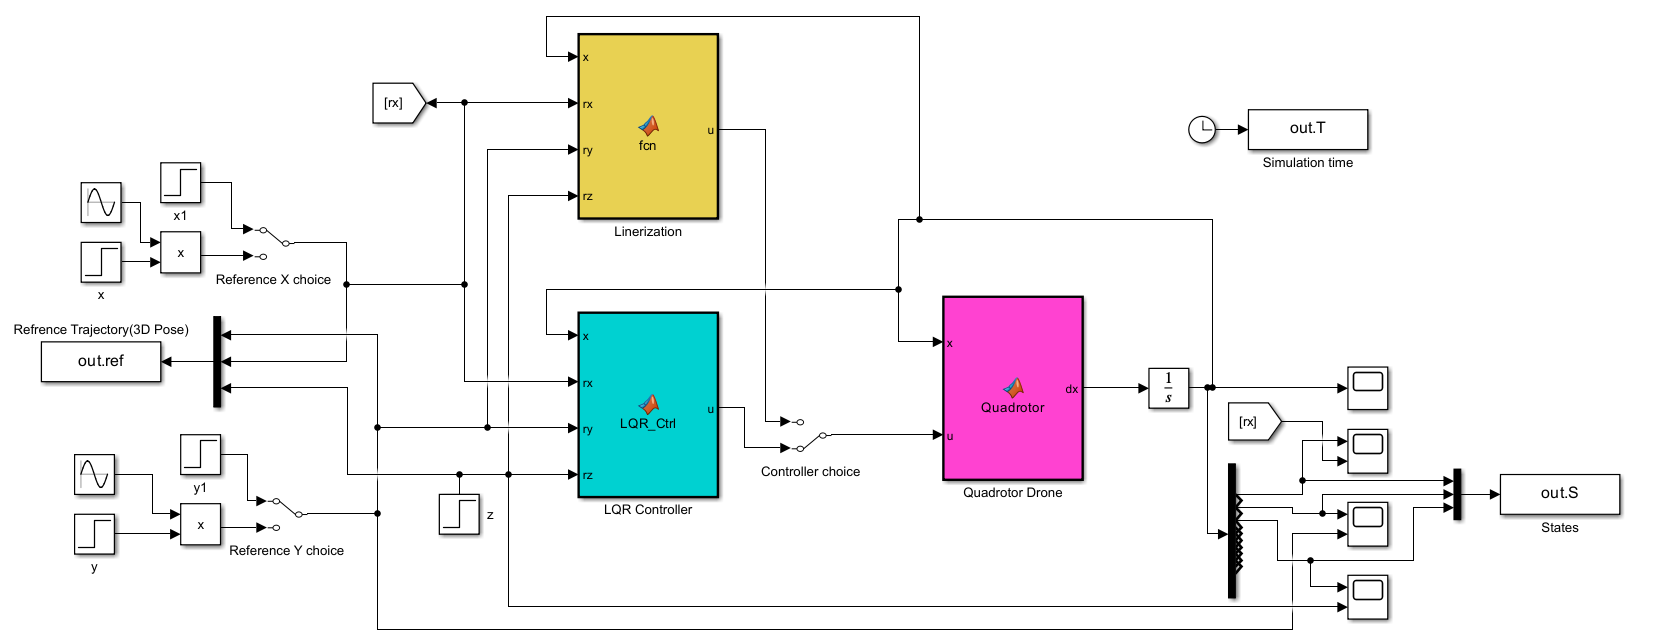

Based on the simulation results, it is evident that the Linear Quadratic Regulator (LQR) controller demonstrates effectiveness in regulating the system. The output of the system closely follows the reference trajectory, showcasing the controller's ability to achieve precise and accurate tracking performance.

**Q4. Modify the control input in order to track :**

**a. Constant trajectory**

Below are the simulation result for the out put tracking the refrence trajectory which is constant.

- **For longitudinal component **$X$** tracking **$X_{\textrm{ref}}$**:**

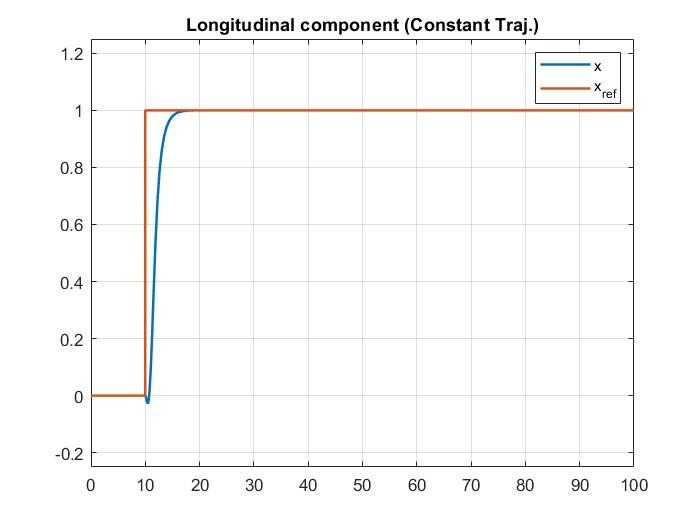

- **For Lateral Component **$Y$** tracking **$Y_{\textrm{ref}}$**:**

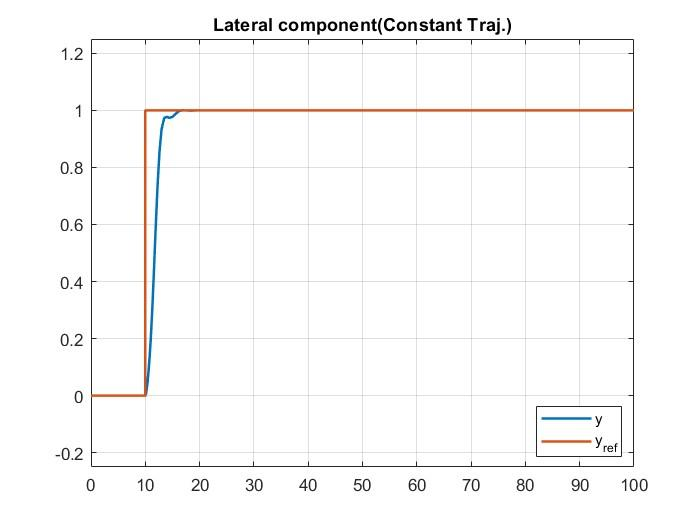

- **For Vertical Component **$Z$** tracking **$Z_{\textrm{ref}}$**:**

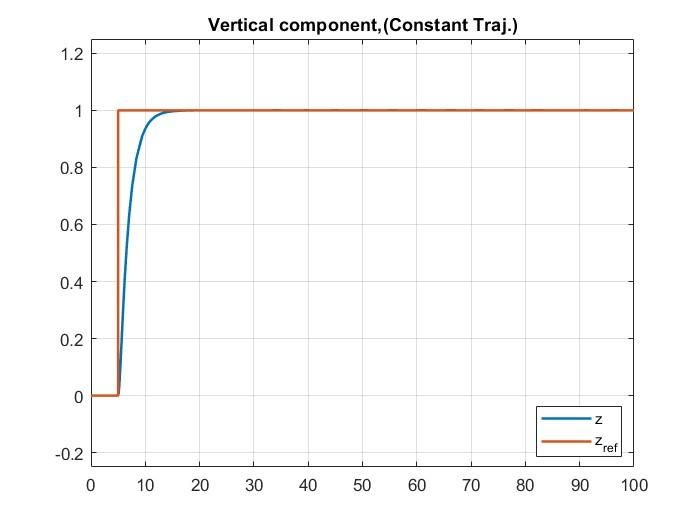

**b. Time varying trajectory**

Below are the simulation result for the out put tracking the refrence trajectory which is constant.

- **For longitudinal component **$X$** tracking **$X_{\textrm{ref}}$**:**

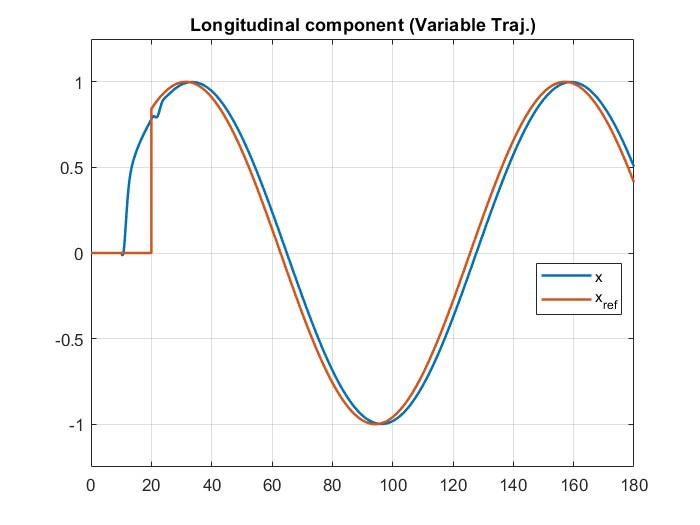

- **For longitudinal component **$X$** tracking **$X_{\textrm{ref}}$**:**

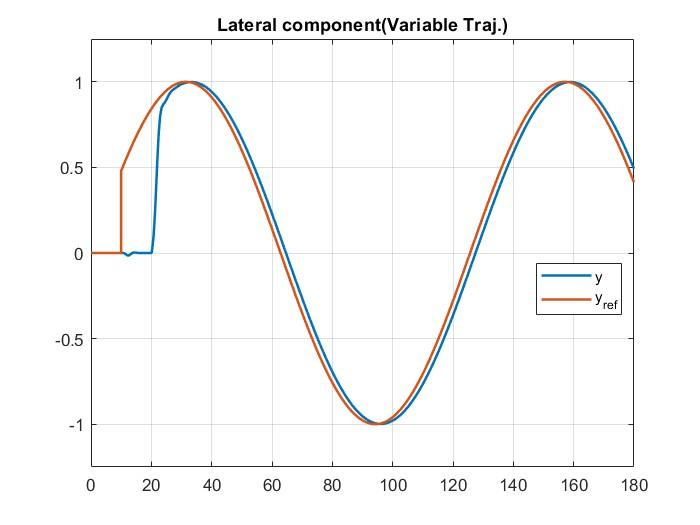

In our observations, the control system exhibits notable characteristics under different scenarios. When the reference trajectory is constant, the control system demonstrates the capability to track with zero static error. This implies that the controlled output precisely aligns with the reference trajectory over time, with no residual deviation. This zero static error indicates a high level of accuracy and precision in the tracking performance of the controller.

On the other hand, when the reference trajectory is varying, the control system showcases its ability to stabilize the system, even in the presence of a small delay. The system's responsiveness to a changing reference trajectory is evident, and the controller successfully mitigates any deviations, ensuring that the output follows the varying reference with minimal error. The small delay observed can be attributed to the time it takes for the control system to adjust and respond to changes in the reference signal.

## 2. Nonlinear longitudinal and lateral control

**Q1. For each motion, compute anonlinear controller by state feedback control with exact linearization approach?**

From our simulink model in our previous section, we swich the controller choice to linearized one to see the reslut of our non linear system.

From the representation of our model we have,the nonlinear langitudinal and lateral model as follow :

**Longitudinal :                                                                         Lateral:**


$$\dot x_1 = x_2\\ 
\dot x_2 = x_{12}x_4 - x_{10}x_6 - g \sin(x_9) + u_1 \\  
\dot x_9 = x_{10} \\
\dot x_{10} = a_2x_{12}x_4 + b_2u_1$$
                                             
$$\dot x_3 = x_2\\ 
\dot x_4 = x_8x_6 - x_{12}x_2 - g \sin(x_7) \cos(x_9) + u_1 \\  
\dot x_9 = x_8 \\
\dot x_{10} = a_2x_{12}x_4 + b_1u_2$$


In essence, our objective is to eliminate the inherent nonlinearities within the system and subsequently implement our controller. This entails a modification of the control inputs to:


$$u_1 = - ( x_{12}x_4 - x_{10}x_6 - g \sin x_9) - K_x (x -x_{ref}) \\ 
u_2 = - (x_8x_6 - x_{12}x_2 - g \sin x_7 \cos x_9) +- K_y (y -y_{ref})$$


**Q2. Apply the proposed control techniques directly on the nonlinear model. Discuss the results.**

We switch our model to the linerized out put as shown below (yellow) block.

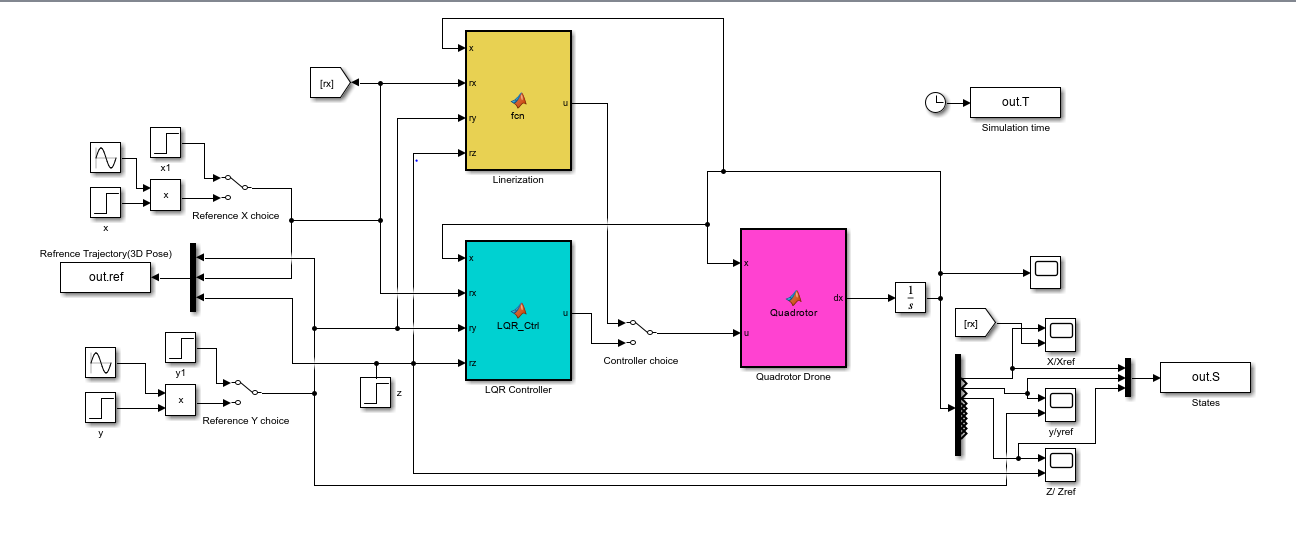

The result shows that our system is more efficient compared to the original version with non-linearities.

**Q3. Modify the control input in order to track :**

Below we will see changing the refrence trajectories.

**(a) a constant trajectory**

- **For longitudinal component **$X$** tracking **$X_{\textrm{ref}}$**:**

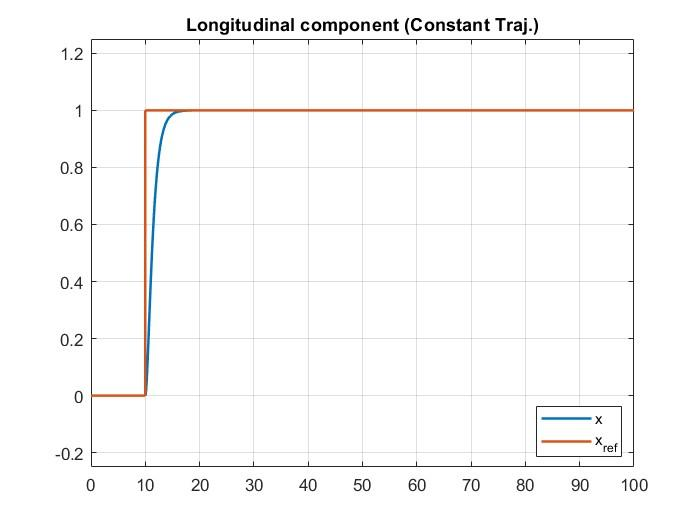

- **For Lateral Component **$Y$** tracking **$Y_{\textrm{ref}}$**:**

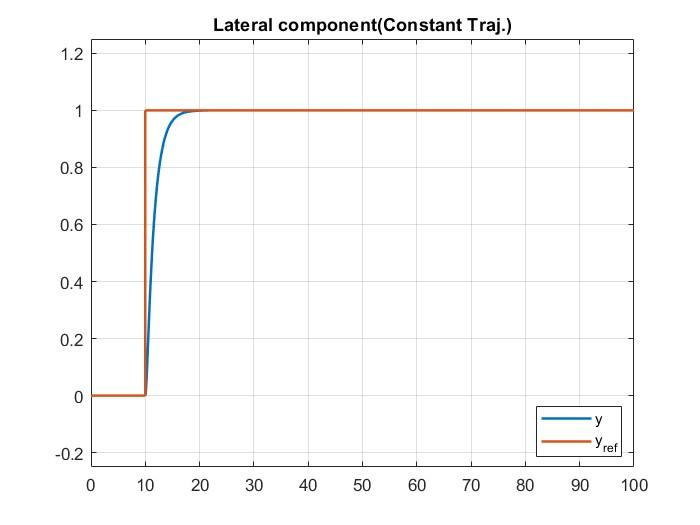

- **For Vertical Component **$Z$** tracking **$Z_{\textrm{ref}}$**:**

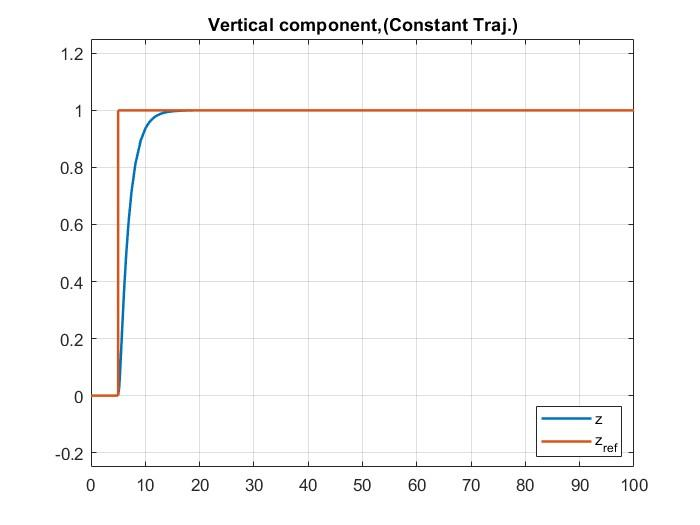

**(b) a time varying trajectory**

**For longitudinal component **$X$** tracking **$X_{\textrm{ref}}$**:**

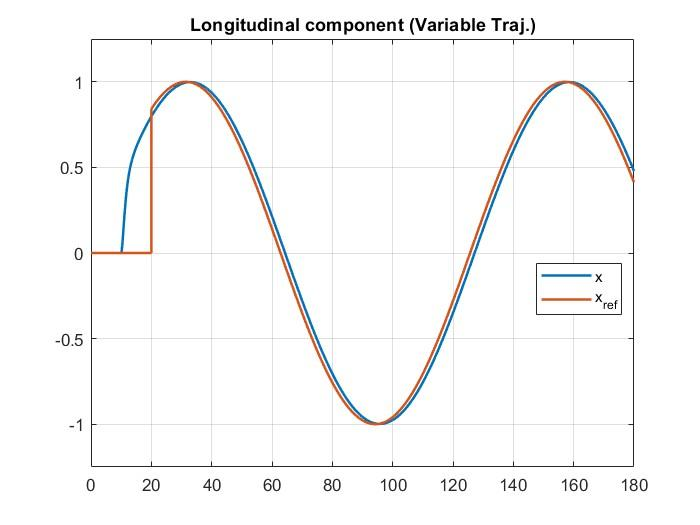

**For Lateral Component **$Y$** tracking **$Y_{\textrm{ref}}$**:**

## 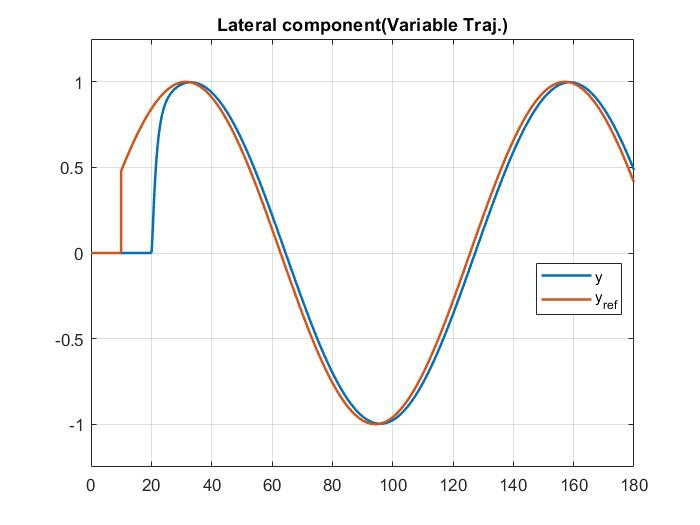

**Q4. Compare the results with the results obtained by the linear controller**

The comparison with linear control showcases the advantageous trait of smooth response transitions, coupled with the important observation of a lingering delay in the variable trajectory, notably in the x and y components. These insights contribute to a nuanced understanding of the control system's performance, emphasizing both strengths and areas for potential refinement.

## **3. Nonlinear Vertical control**

**Q1. Prove that the following control inputs allows to obtain a linear closed-loop system and compute the values of k1, k2, k3 and k4 allonwing to stabilize asymptotically the system.**

We consider the two controllers given as follow:-


$$u_3 = -x_{10}x_2 + x_8x_4 +g\cos x_7 \cos x_9 - k_1x_5 - k_2x_6 \\ 
u_4 = -a_3x_8x_{10} - \frac {1}I_{xx}M_3 -k_3x_{11} - k_4x_{12}$$


we repalce the above two equations on the non-linear vertical model and we will get the following reslul.

 
$$\begin{array}{l}
{\dot{x} }_6 =x_{10} x_2 -x_8 x_4 +g\;\cos \left(x_7 \right)\cos \left(x_9 \right)-\left(x_{10} x_2 -x_8 x_4 +g\;\cos \left(x_7 \right)\cos \left(x_9 \right)\right)-k_1 x_5 -k_2 x_6 \\
{\dot{x} }_{12} =a_3 x_8 x_{10} +\frac{1}{I_{\textrm{xx}} }M_3 -\left(a_3 x_8 x_{10} -\frac{1}{I_{\textrm{xx}} }M_3 \right)-k_3 x_{11} -k_4 x_{12} 
\end{array}$$


then ,


$$\begin{array}{l}
{\dot{x} }_5 =x_6 \\
{\dot{x} }_6 =-k_1 x_5 -k_2 x_6 \\
{\dot{x} }_{11} =x_{12} \\
{\dot{x} }_{12} =-k_3 x_{11} -k_4 x_{12} 
\end{array}$$


So the above equations can be represented by state space matrix form as follows:


$$\left\lbrack \begin{array}{c}
{\dot{x} }_5 \\
{\dot{x} }_6 \\
{\dot{x} }_{11} \\
{\dot{x} }_{12} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-k_1  & -k_2  & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & -k_3  & -k_4 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_5 \\
x_6 \\
x_{11} \\
x_{12} 
\end{array}\right\rbrack =A\ldotp x$$


From the representation its observed that we can compute $K=\left\lbrack \begin{array}{cccc}
k_1  & k_2  & k_3  & k_4 
\end{array}\right\rbrack$, by using carateristic equation of eignevector $\det \left(\lambda I-A\right)=0$. where $\lambda$ are the eigenvalue of *A *, and we can write $A=\left\lbrack \begin{array}{cc}
A_1  & 0\\
0 & A_2 
\end{array}\right\rbrack$, so the caracteristic equation will be : $\det \left(\lambda I-A_1 \right)\ldotp \det \left(\lambda I-A_2 \right)=0$. So finally we willl solve for K values.

**Q2. Simulate the vertical model with a 0-reference z position and a non-zero constant and positive position**

**(Hovering flight).**

Here, we will use the model with the modified control inputs, implemented in the following simulink model:

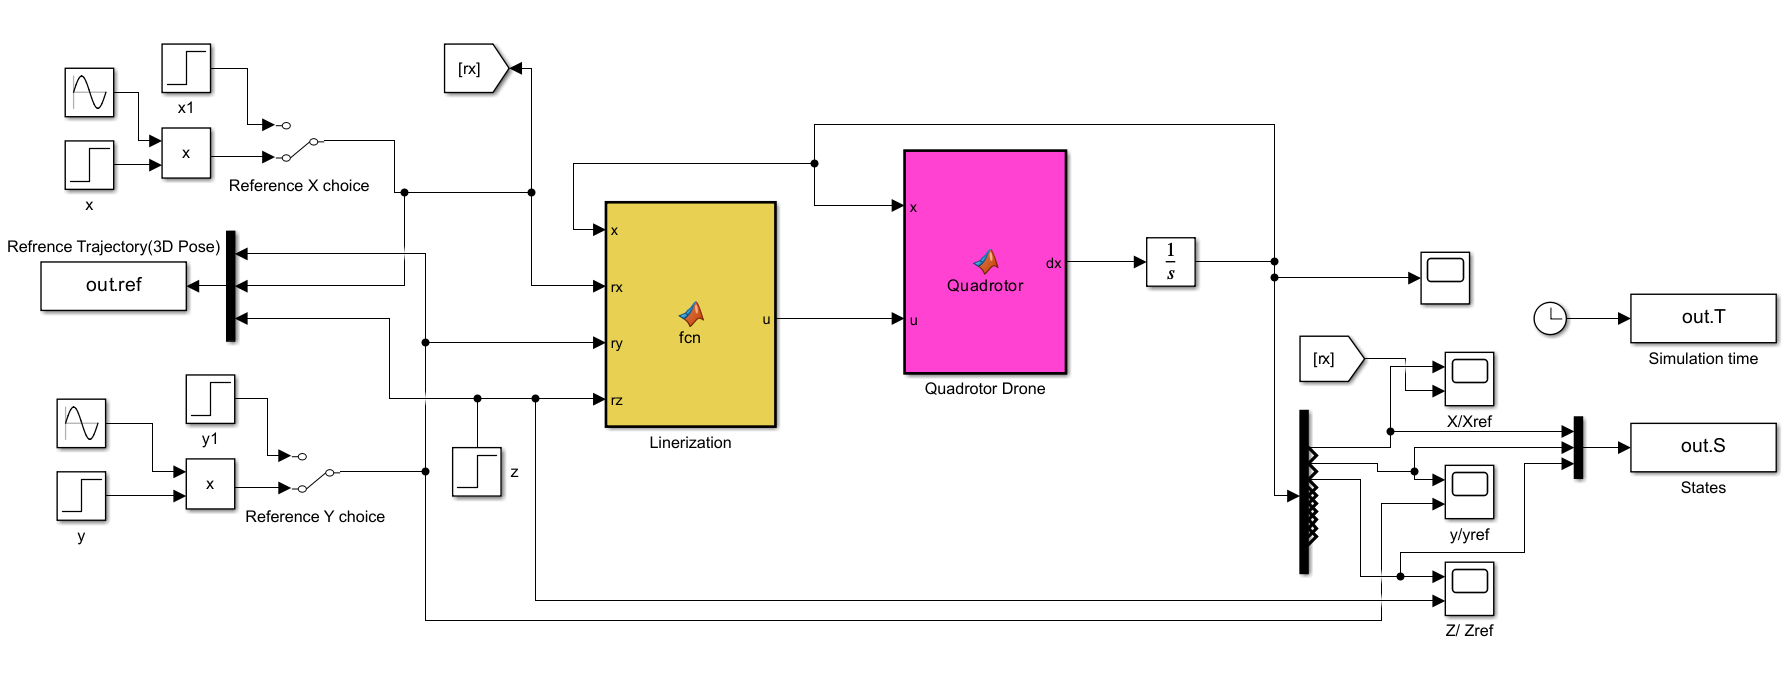

**a)  0-reference z position:**

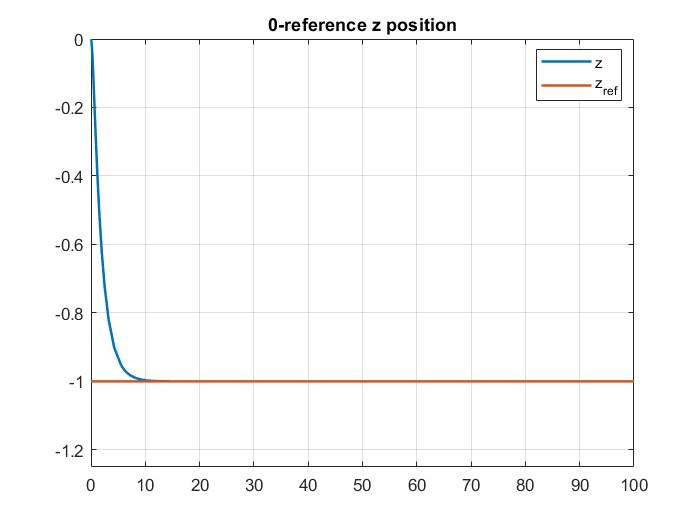

**b) Hovering Flight ( Non-zero constant and positive position)**

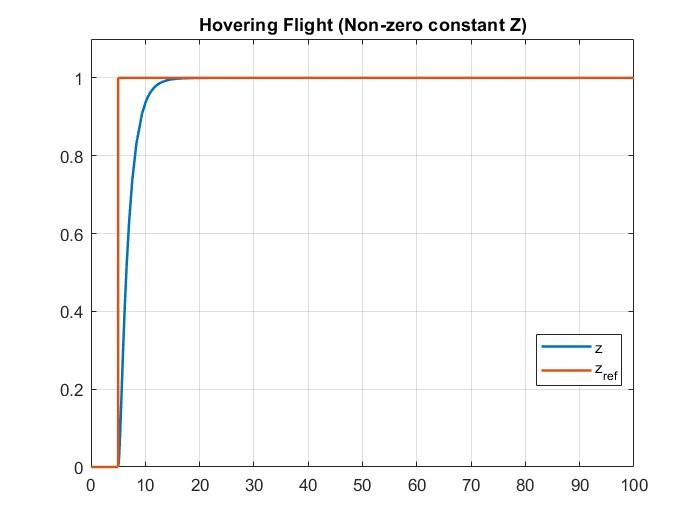

## 4. Autonomous control of the complete system

In this section, the previous controllers will be applied to the complete model.

**Q1. Simulate the closed loop system with a setpoint in zero position.**

Below are the simulation results of closed loop system for both linear and Non-linear systems at zero reference.

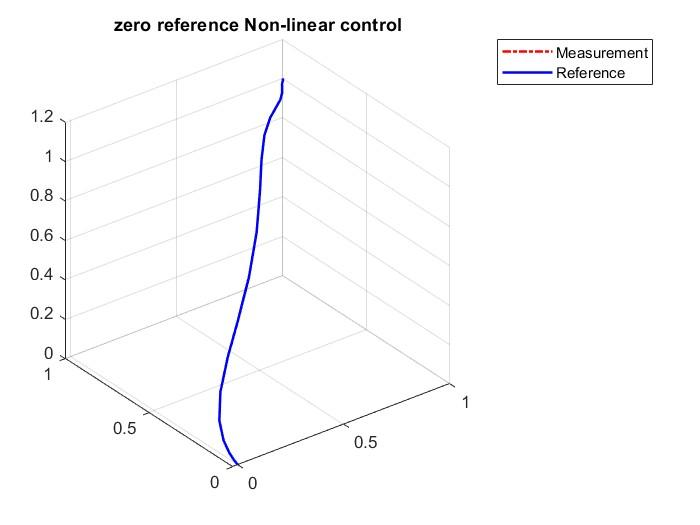

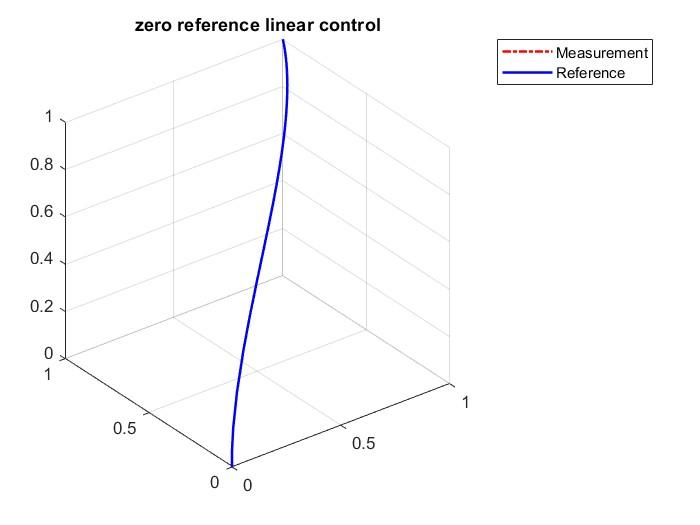

**Q2. Simulate the closed loop system with a reference trajectory.**

(a) Vertical and hovering flights at 1m, for 10s longitudinal flight at 1m, for 20s lateral fight 1m, at 40s landing.

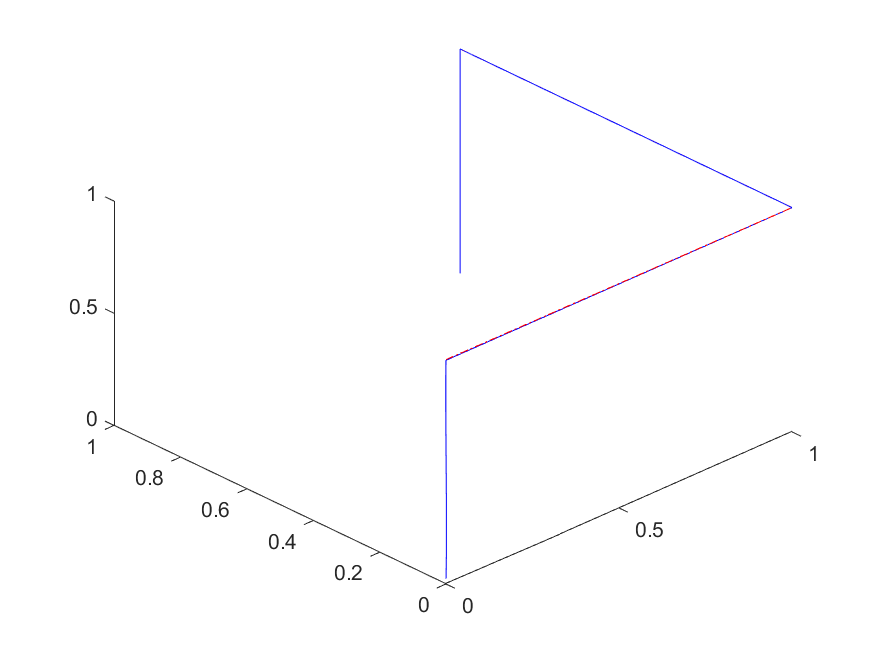

**Q3. Simulate the closed loop system with :**

Vertical and hovering fights at 1m, and a Circle flight in the x, y plan